# Lecture 12 - Noise and speech signal distributions

In this LiveScript we are looking into the statistical description of signals and will touch upon how some properties are reflected in the intensity of a acoustic signal.

## Noise and noise

Let's have a look at a noise signal (white noise) in the time domain and in terms of its statistical descriptors (moments).

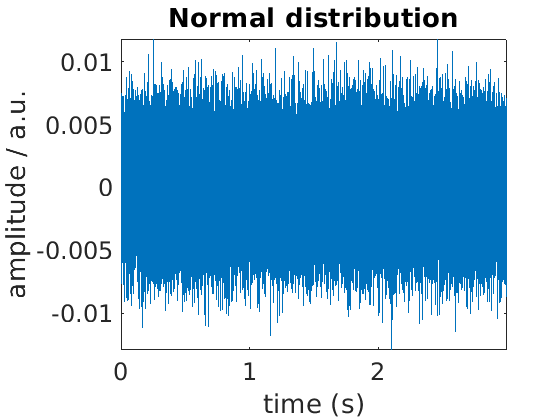

clear all; close all;
% some parameters
fs = 44100;
T = 3;
n_scale = 1;    % scaling parameter of noise signal
t = 0:1/fs:T-1/fs;    % time vector for plotting
% file names
path2wav = ['..', filesep, 'sounds', filesep];
fname_speech = 'spoken_sentence.wav';

% generate noise signals
n_norm_raw = randn(fs*T,1);    % get a normally distributed noise signal
n_uni_raw = rand(fs*T,1)-.5;   % get a uniformly distributed noise signal

% normalize RMS value
n_norm = n_norm_raw/(sqrt(mean(sum(n_norm_raw.^2))));
n_uni = n_uni_raw/(sqrt(mean(sum(n_uni_raw.^2))));
% load speech signal
fname = [path2wav, fname_speech];
[Y, fs_audio] = audioread(fname);
Y = resample(Y,fs, fs_audio);
Y_norm = Y/(sqrt(mean(sum(Y.^2))));    % normalize RMS value
t_audio = 0:1/fs: length(Y)/fs-1/fs;

% plot the signals
h1 = plot(t,n_norm);
xlabel('time (s)'); ylabel('amplitude / a.u.'); title('Normal distribution')
set(gca,'Fontsize',18); axis tight;

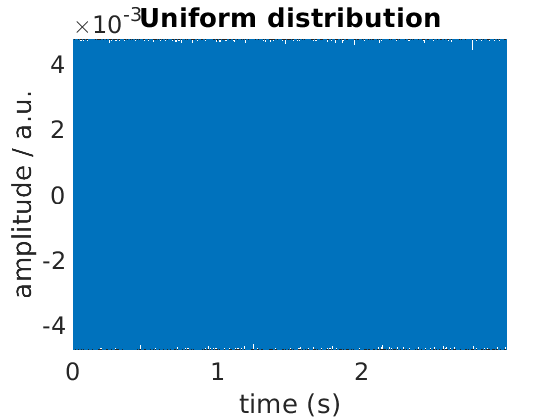


h2 = plot(t,n_uni);
xlabel('time (s)'); ylabel('amplitude / a.u.'); title('Uniform distribution')
set(gca,'Fontsize',18); axis tight;


return

**The signal looks completely different!**

## Moments and sound

What we have now are two noise signals and one speech audio signal. Let's caclulate the forst two moments and have a listen!

% calculate mean and variance for each signal
mean_norm = mean(n_norm);
var_norm = var(n_norm);

mean_uni = mean(n_uni);
var_uni = var(n_uni);

% listen to the signals:
disp('Noise signal: normally distributed');

Noise signal: normally distributed


disp(['\mu =', num2str(mean_norm), ' \sigma^2 = ', num2str(var_norm)]);

\mu =1.243e-05 \sigma^2 = 7.5585e-06


sound(n_scale*n_norm,fs);

pause(length(n_norm)/fs + 2);

disp('Noise signal: uniformly distributed')

Noise signal: uniformly distributed


disp(['\mu =', num2str(mean_uni), ' \sigma^2 = ', num2str(var_uni)]);

\mu =6.1566e-06 \sigma^2 = 7.5586e-06


sound(n_scale*n_uni,fs);

**The (first and second) moments are (essentially) the same!**

## Distributions

That is odd. They are different, but somewhat the same. Let's look at their distributions and see if what we see makes sense. We'll compute the histograms of the samples as an estimator of the probability density function:

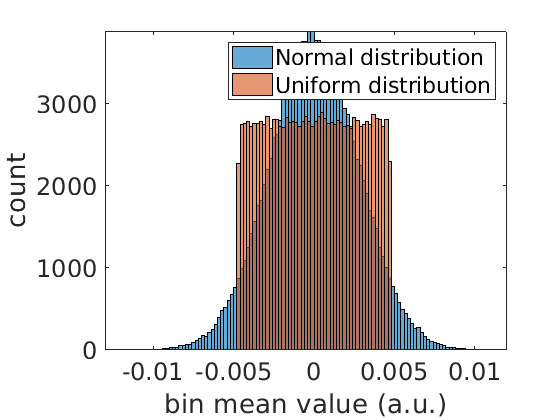

% calculate the histograms 
figure
h_norm = histogram(n_norm); hold on;
h_uni = histogram(n_uni);

xlabel('bin mean value (a.u.)')
ylabel('count')
set(gca,'Fontsize',18); axis tight;
legend({'Normal distribution','Uniform distribution'})

**...finally, one can see a difference in the distributions of the samples!**

## What do moments do?

It would be interesting to see what moments actually do. So let's scale the amplitude of the noise (we'll look at the variance, the mean is anyways almost zero) and see what will happen!

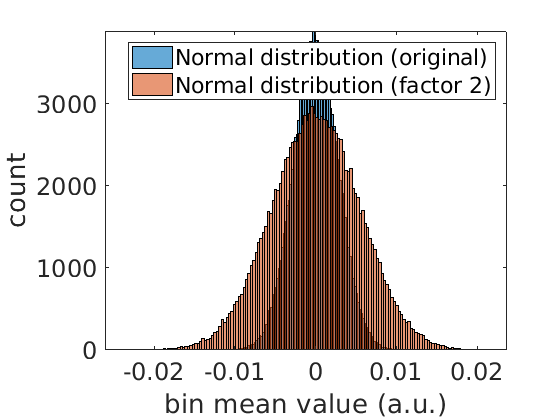

% we'll only look at the normally distributed
n_norm_2 = 2*n_norm;
n_norm_5 = 5*n_norm;

var_norm_2 = var(n_norm_2);
var_norm_5 = var(n_norm_5);

% display the results and play back
figure
h_norm = histogram(n_norm); hold on;
h_norm_2 = histogram(n_norm_2);
xlabel('bin mean value (a.u.)')
ylabel('count')
set(gca,'Fontsize',18); axis tight;
legend({'Normal distribution (original)','Normal distribution (factor 2)'})

disp('Noise signal: normally distributed (original)');

Noise signal: normally distributed (original)


disp([' \sigma^2 = ', num2str(var_norm)]);

 \sigma^2 = 7.5585e-06


sound(n_scale*n_norm,fs);
pause(length(n_norm)/fs + 1);
disp('Noise signal: normally distributed (factor 2)');

Noise signal: normally distributed (factor 2)


disp([' \sigma^2 = ', num2str(var_norm_2)]);

 \sigma^2 = 3.0234e-05


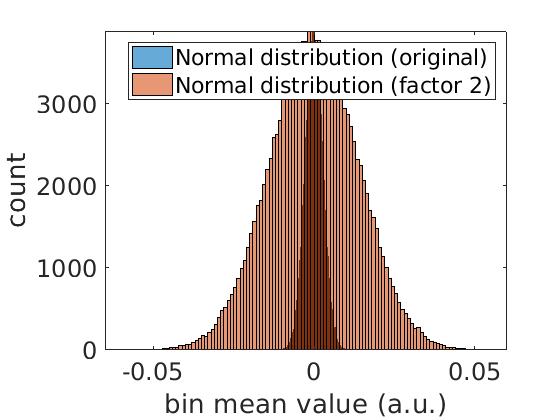

sound(n_scale*n_norm_2,fs);
pause(length(n_norm_2)/fs + 1);


figure
h_norm = histogram(n_norm); hold on;
h_norm_5 = histogram(n_norm_5);
xlabel('bin mean value (a.u.)')
ylabel('count')
set(gca,'Fontsize',18); axis tight;
legend({'Normal distribution (original)','Normal distribution (factor 5)'})


disp('Noise signal: normally distributed (factor 5)');

Noise signal: normally distributed (factor 5)


disp([' \sigma^2 = ', num2str(var_norm_5)]);

 \sigma^2 = 0.00018896


sound(n_scale*n_norm_5,fs);
pause(length(n_norm_5)/fs + 1);

**The level of the sound depends on the variance of the signal!**

## And what about speech signals?

Speech and noise have different statistical properties - this can be used to deparate speech and noise. Let's have a look:

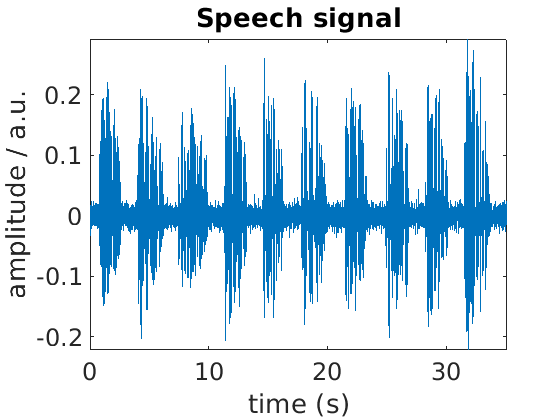

% Plot the distributions of the speech signal and a noise of same length
n_speech = randn(length(Y),1);
n_norm_speech = n_speech/(sqrt(mean(sum(n_speech.^2))));

figure
plot(t_audio,Y);
xlabel('time (s)'); ylabel('amplitude / a.u.'); title('Speech signal')
set(gca,'Fontsize',18); axis tight;

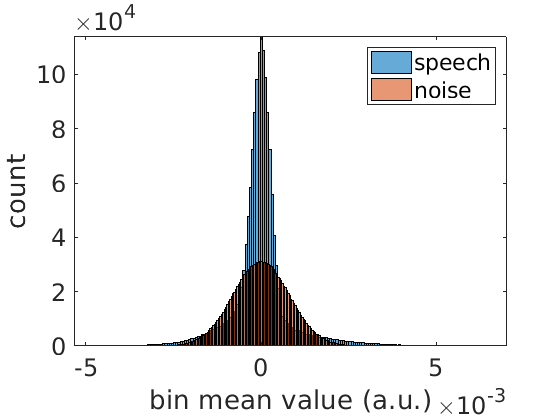



figure
histogram(Y_norm,200); hold on;
histogram(n_norm_speech,200);
xlabel('bin mean value (a.u.)')
ylabel('count')
set(gca,'Fontsize',18); axis tight;
legend({'speech','noise'});

**Speech has a much more "sharp" distribution than a continuous noise...**

Wooow! What about noisy speech?

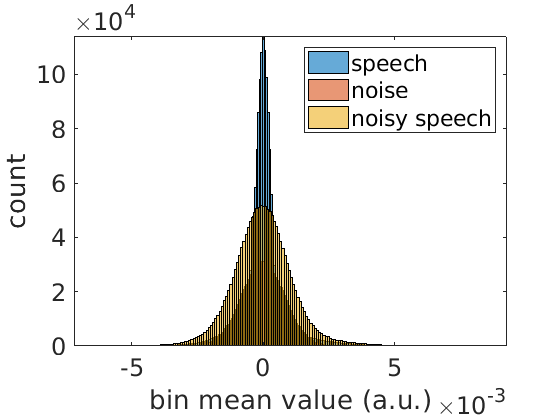

% mix speech and noise
noisy_speech = Y_norm+n_norm_speech;
sound(noisy_speech,fs)

figure
histogram(Y_norm,200); hold on;
histogram(n_norm_speech,200);
histogram(noisy_speech,200);
xlabel('bin mean value (a.u.)')
ylabel('count')
set(gca,'Fontsize',18); axis tight;
legend({'speech','noise', 'noisy speech'});

**...if you now get an estimate of the noise (e.g., in the periods where the sound signal is rather "noisy", one might estimate which samples are dominantly noise and try to separate those from the noisy signal.**

**...that is something from the domain of "statistical signal processing"...**